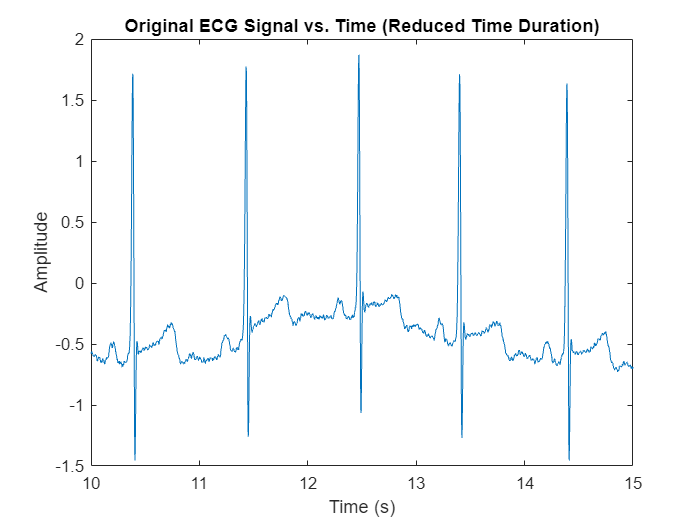

% Load the ECG signal data
fileID = load('database\RECORDS');
file_name = int2str(fileID(15));
file_path = fullfile('database', file_name);
[signal, Fs, Tm] = rdsamp(file_path, 1);

% Define the start and end times for the selected time range
start_time = 10;
end_time = 15;

% Find the indices corresponding to the selected time range
start_idx = find(Tm >= start_time, 1);
end_idx = find(Tm >= end_time, 1);

% Extract the selected time and signal data
selected_tm = Tm(start_idx:end_idx);
selected_signal = signal(start_idx:end_idx);

% Plot the original ECG data for the selected time range
figure;
plot(selected_tm, selected_signal);
title('Original ECG Signal vs. Time (Reduced Time Duration)');
xlabel('Time (s)');
ylabel('Amplitude');

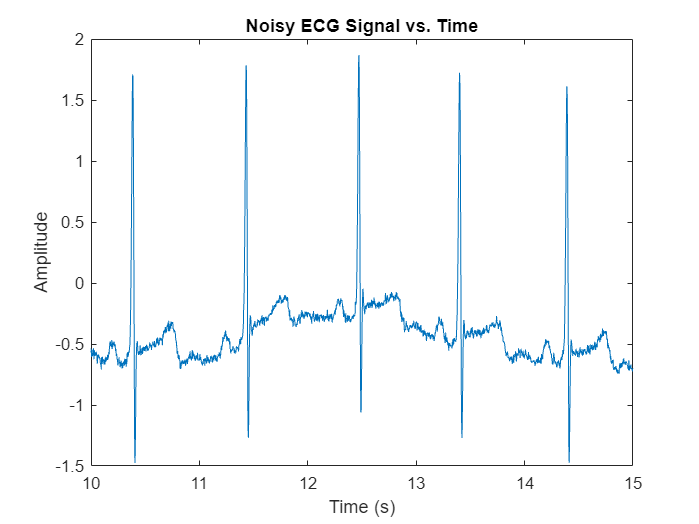


% Parameters for adding noise to the signal
SNR_dB = 25;
noise = randn(size(selected_signal));
scaling_factor = 10^(-SNR_dB / 20) * std(selected_signal) / std(noise);

% Create a noisy version of the selected signal
noisy_signal = selected_signal + scaling_factor * noise;

% Plot the noisy signal
figure;
plot(selected_tm, noisy_signal);
title('Noisy ECG Signal vs. Time');
xlabel('Time (s)');
ylabel('Amplitude');

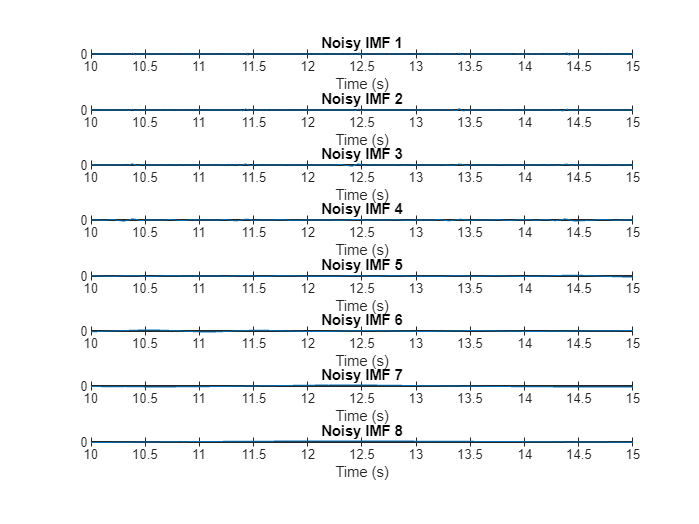


% Perform Empirical Mode Decomposition (EMD) on the noisy signal
imfs = emd(noisy_signal);
% Plot the noisy IMFs
figure;
for i = 1:size(imfs, 2)
    subplot(size(imfs, 2), 1, i);
    plot(selected_tm, imfs(:, i));
    title(['Noisy IMF ' num2str(i)]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

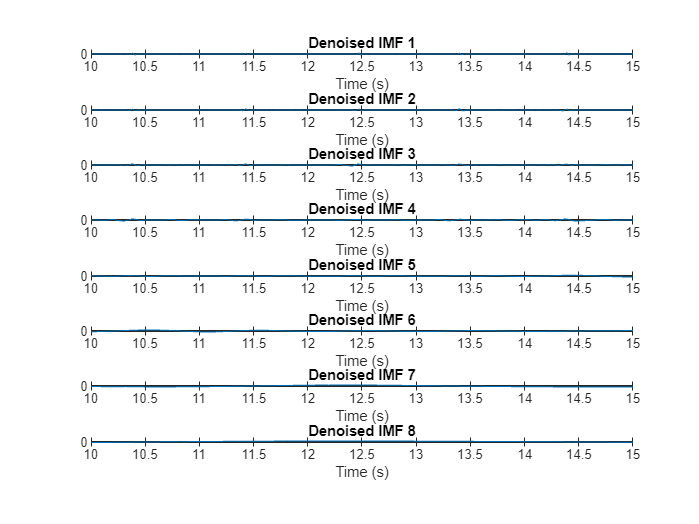

% Initialize the residue
residue = zeros(size(noisy_signal));

% Sifting process
for iteration = 1:10
    % Reconstruct signal from selected IMFs
    reconstructed_signal = sum(imfs(:, 1:end-1), 2);
    
    % Calculate the residue
    residue = noisy_signal - reconstructed_signal;
    
    % Apply EMD to the residue
    imfs = emd(residue);
end

% Create a denoised version of each IMF
denoised_imfs = zeros(size(imfs));

for i = 1:size(imfs, 2)
    % Define appropriate values for level, wavelet, and threshold
    level = 5;
    wavelet = 'db4';
    threshold = 's';

    denoised_imfs(:, i) = wdenoise(imfs(:, i), level, 'Wavelet', wavelet, 'DenoisingMethod', threshold);
end

% Plot the denoised IMFs
figure;
for i = 1:size(denoised_imfs, 2)
    subplot(size(denoised_imfs, 2), 1, i);
    plot(selected_tm, denoised_imfs(:, i));
    title(['Denoised IMF ' num2str(i)]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

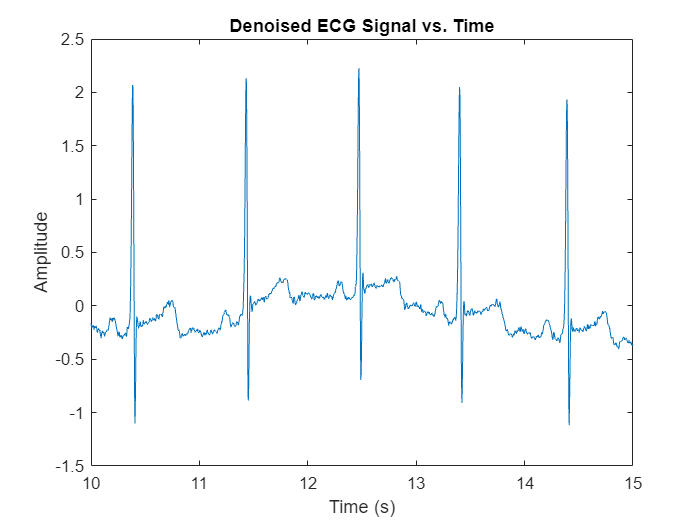


% Reconstruct the denoised signal by summing the denoised IMFs
denoised_signal = sum(denoised_imfs, 2);

% Plot the denoised signal
figure;
plot(selected_tm, denoised_signal);
title('Denoised ECG Signal vs. Time');
xlabel('Time (s)');
ylabel('Amplitude');


% Calculate Signal-to-Noise Ratio (SNR) for noisy and denoised signals
NoisySNR = snr(selected_signal, noisy_signal);
DenoisedSNR = snr(selected_signal, denoised_signal);

% Calculate Root Mean Square Error (RMSE)
rmse = sqrt(mean((denoised_signal - selected_signal).^2));

disp('SNR of Noisy signal:')

SNR of Noisy signal:


disp(NoisySNR)

   -0.0093



disp('SNR of Denoised signal:')

SNR of Denoised signal:


disp(DenoisedSNR)

    4.0843



disp('Root Mean Square Error (RMSE):')

Root Mean Square Error (RMSE):


disp(rmse)

    0.3635

